% формирование массива времени (часы) и температуры воздуха, из листов с данными ГИС КС, МГ
d = dir('C:\Users\user\MATLAB Drive\1Exponenta\data good\data_4_GRS');

d(1:3) = []; %обнуление 
t1 = []; %создание пустого массива

for i = 1:numel(d)
    disp(i) % демо считывания данных по месяцам
    str = d(i).folder +"\"+ d(i).name; % считываем имя файла в директории d
    [a,txt] = readfile_all(str); % читаем файл, к которому обращаемся
    b = txt(6:end,2); % заменили формат, в ктором указано время (часы), на читаемый 
    B = ismissing(b);% заменили формат, в ктором указано время (часы), на читаемый 
    b(B) = [];% заменили формат, в ктором указано время (часы), на читаемый 
    c = categorical(b);% заменили формат, в ктором указано время (часы), на читаемый 
    b1 = double(c);% заменили формат, в ктором указано время (часы), на читаемый 
    t1 = [t1; [b1, a(:,1:8)]];% 
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12



Q_gis = t1(:,9);

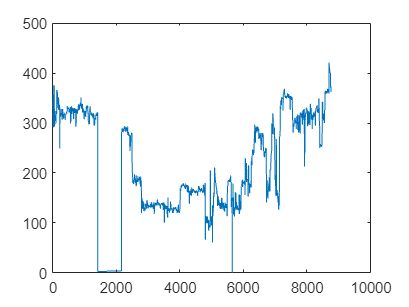

plot(Q_gis);

save dataGIS_total t1

function [t1,txt] = readfile_all(str)
[t1,txt] = xlsread(str,'КС, МГ');
s = all(isnan(t1));
t1(:,s) = [];
b = all(isnan(t1),2);
t1(b,:) = [];
end